# Streaming Data from Rotman Interactive Trader to MATLAB®

This example shows how to connect to and stream data from Rotman Interactive Trader (RIT) using `rotmanTrader` functionality. RIT must be installed on your computer along with the Excel RTD Links. For more information visit [http://rit.rotman.utoronto.ca/software.asp](http://rit.rotman.utoronto.ca/software.asp). This example also assumes that RIT is running Liability Trading 3 Case.

## Create a Connection

First step is to create a connection to RIT. To do this, issue the `rotmanTrader` command.

rit = rotmanTrader

rit =   rotmanTrader with properties:

            updateFreq: 2
            lastUpdate: '08-Feb-2018 12:42:02'
           updateTimer: [1×1 timer]
            updateFcns: {}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 297
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0


Notice that the rit connection has properties listed. These default properties are always available and update with the frequency listed in the updateFreq property. The default value is 2 seconds. Also listed is the last update timestamp in lastUpdate. To change the update frequency, set the property to a different value. For example, to change it to 1 seconds:

rit.updateFreq = 1

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:02'
           updateTimer: [1×1 timer]
            updateFcns: {}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 297
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0


## Subscribing to RIT Data

Data is retrieved from RIT using the same server that is used for Microsoft Excel. In RIT, you can click on the RTD link in the bottom right corner. It will bring up this image with available data fields.

<<rtd_fields.png>>

In Excel, you use the RTD function to return data. In MATLAB, you use the `subscribe` command to enter the field information for the data you wish to subscribe to. This will add the data to the rit variable we created earlier. For example, to get the last traded price we need to enter two fields, the ticker symbol and the LAST string separated by a |. For example, to subscribe to security CRZY and add the LAST price to our connection to RIT (the rit variable defined earlier), type

subscribe(rit,'CRZY|LAST')
rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:03'
           updateTimer: [1×1 timer]
            updateFcns: {}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 296
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
             crzy_last: 10


You can see that RIT now has a new property of crzy_last that will update with last traded prices. Subscriptions added will show up as additional properties. To return the data, simply type

rit.crzy_last

ans = 9.9700

Note that when `subscribe` is called, data is updated from RIT. You can also force an update by issuing `update`

update(rit)

ans =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:06'
           updateTimer: [1×1 timer]
            updateFcns: {}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 293
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
             crzy_last: 9.9700


rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:06'
           updateTimer: [1×1 timer]
            updateFcns: {}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 293
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
             crzy_last: 9.9700


We could also add the bid and ask as well. Note the need to separate the list of two subscriptions by ";" is required.

subscribe(rit,{'CRZY|BID';'CRZY|ASK'})
rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:07'
           updateTimer: [1×1 timer]
            updateFcns: {}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 292
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
              crzy_bid: 9.9800
              crzy_ask: 9.9900
             crzy_last: 9.9700


We could also obtain the latest news using LATESTNEWS|N where Nth is the order of latest news (most recent first)

subscribe(rit,'LATESTNEWS|1')
rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:08'
           updateTimer: [1×1 timer]
            updateFcns: {}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 291
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
              crzy_bid: 9.9800
          latestnews_1: '1,0,,Welcome to the Liability Trading 3 Case,'
              crzy_ask: 9.9900
             crzy_last: 9.9900


## Working with Streaming Data

To work with streaming data, you add a function that is called each time data is updated. To do this, let's first create a function that will display the last price for CRZY.

fcn = @(input) disp(['CRZY Last Traded at $',num2str(input.crzy_last,'%4.2f')])

fcn = function_handle with value:
    @(input)disp(['CRZY Last Traded at $',num2str(input.crzy_last,'%4.2f')])


newsFcn = @(input) extractNews(input.latestnews_1)

newsFcn = function_handle with value:
    @(input)extractNews(input.latestnews_1)


What we created here was a function that will print to the command window the last traded price for CRZY every time an update is called for `rotmanTrader` (every second in this case). The input in this case is the `rotmanTrader` variable. For example, test the function:

fcn(rit)

CRZY Last Traded at $9.99


newsFcn(rit)

Latest news: Welcome to the Liability Trading 3 Case


Now add it to the list of updateFcns and it will be executed every time there is an update.

addUpdateFcn(rit,fcn)
addUpdateFcn(rit,newsFcn)
rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:13'
           updateTimer: [1×1 timer]
            updateFcns: {'@(input)disp(['CRZY Last Traded at $',num2str(input.crzy_last,'%4.2f')])'  '@(input)extractNews(input.latestnews_1)'}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 286
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
              crzy_bid: 9.9500
          latestnews_1: '1,0,,Welcome to the Liability Trading 3 Case,'
              crzy_ask: 10.0100
             crzy_last: 10.0100


pause(10)

Add another function for bids and asks

askfcn = @(input) disp(['CRZY ASK Price is $',num2str(input.crzy_ask,'%4.2f')])

askfcn = function_handle with value:
    @(input)disp(['CRZY ASK Price is $',num2str(input.crzy_ask,'%4.2f')])


addUpdateFcn(rit,askfcn)
bidfcn = @(input) disp(['CRZY BID Price is $',num2str(input.crzy_bid,'%4.2f')])

bidfcn = function_handle with value:
    @(input)disp(['CRZY BID Price is $',num2str(input.crzy_bid,'%4.2f')])


addUpdateFcn(rit,bidfcn)
rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:23'
           updateTimer: [1×1 timer]
            updateFcns: {1×4 cell}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 276
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
              crzy_bid: 10.0500
          latestnews_1: '1,0,,Welcome to the Liability Trading 3 Case,'
              crzy_ask: 10.0800
             crzy_last: 10.0800


pause(10)

Note that updateFcns is 1x3 cell array listing the functions that will be executed with each update.

rit.updateFcns{:}

ans = '@(input)disp(['CRZY ASK Price is $',num2str(input.crzy_ask,'%4.2f')])'

ans = '@(input)disp(['CRZY BID Price is $',num2str(input.crzy_bid,'%4.2f')])'

ans = '@(input)disp(['CRZY Last Traded at $',num2str(input.crzy_last,'%4.2f')])'

ans = '@(input)extractNews(input.latestnews_1)'

To stop the updates, simply remove the function from the list using the `removeUpdateFcn` and pass in function name to remove. We'll remove the last traded price

removeUpdateFcn(rit,rit.updateFcns{3})
rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:33'
           updateTimer: [1×1 timer]
            updateFcns: {'@(input)disp(['CRZY ASK Price is $',num2str(input.crzy_ask,'%4.2f')])'  '@(input)disp(['CRZY BID Price is $',num2str(input.crzy_bid,'%4.2f')])'  '@(input)extractNews(input.latestnews_1)'}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 266
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
              crzy_bid: 10.0100
          latestnews_1: '1,0,,Welcome to the Liability Trading 3 Case,'
              crzy_ask: 10.0300
             crzy_last: 9.9900


pause(10)

Remove the bid, ask, and news functions

rit.updateFcns{:}

ans = '@(input)disp(['CRZY ASK Price is $',num2str(input.crzy_ask,'%4.2f')])'

ans = '@(input)disp(['CRZY BID Price is $',num2str(input.crzy_bid,'%4.2f')])'

ans = '@(input)extractNews(input.latestnews_1)'

removeUpdateFcn(rit,rit.updateFcns{3})
removeUpdateFcn(rit,rit.updateFcns{2})
removeUpdateFcn(rit,rit.updateFcns{1})
rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:42:44'
           updateTimer: [1×1 timer]
            updateFcns: {1×0 cell}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 255
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
              crzy_bid: 9.9300
          latestnews_1: '1,0,,Welcome to the Liability Trading 3 Case,'
              crzy_ask: 9.9500
             crzy_last: 9.9500


pause(10)

## Create a Plot that Updates with New Data

Create a simple plot that has bid, ask, and last trade price for CRZY and adds data to the plot as `rit` updates.

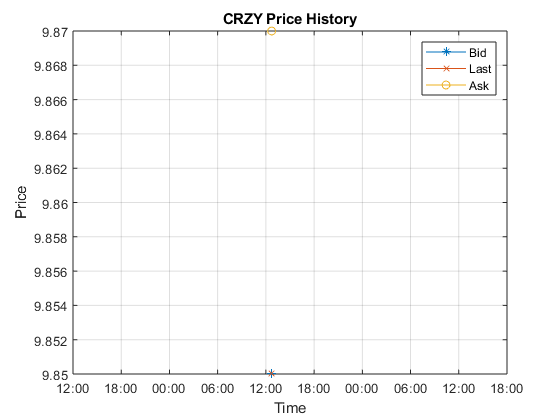

h = plot(datenum(rit.lastUpdate),rit.crzy_bid,'-*', ...
     datenum(rit.lastUpdate),rit.crzy_last,'-x', ...
     datenum(rit.lastUpdate),rit.crzy_ask,'-o');
grid on
datetick
legend('Bid','Last','Ask')
ylabel('Price')
xlabel('Time')
title('CRZY Price History')

Define a function to update the plot

type updatePlotFcn


function updatePlotFcn(h,data)
%UPDATEPLOTFCN is an example function for updating a line plot

% Copyright 2015 The MathWorks, Inc.

% update x axis
x = datenum(data.lastUpdate);
h(1).XData(end+1) = x;
h(2).XData(end+1) = x;
h(3).XData(end+1) = x;

% update y axis
h(1).YData(end+1) = data.crzy_bid;
h(2).YData(end+1) = data.crzy_last;
h(3).YData(end+1) = data.crzy_ask;

% update plot format
datetick('x','HH:MM:SS');
xlim('auto');
drawnow;


Test the function by adding a new update and set x axis updating to auto

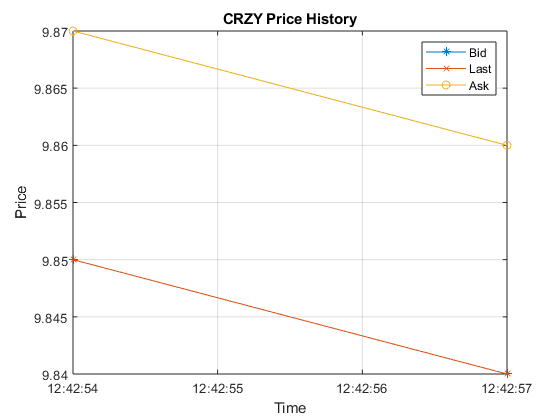

updatePlotFcn(h,rit)

Add it to updateFcns list

addUpdateFcn(rit,@(input) updatePlotFcn(h,input));

Watch the plot update

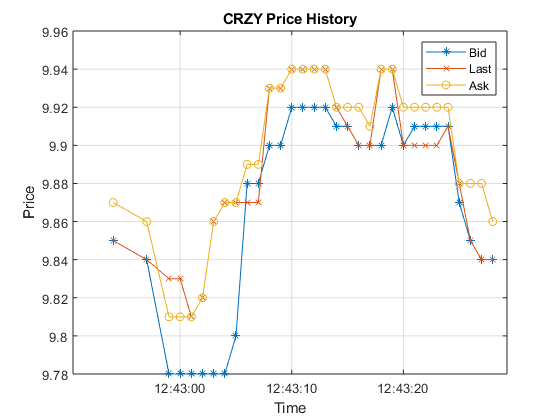

pause(30)

gcf;

remove plot update function before unsubscribing

removeUpdateFcn(rit,rit.updateFcns{1})

## Unsubscribing

To unsubscribe from a source of data, use `unsubscribe`. Note that if you have any update functions that are using this data, you need to remove them first.

Unsubscribe from the bid price for CRZY. First get the subscription list and IDs

topics = getSubscriptions(rit)

topics = 4×2 table
    ID        Topic     
    __    ______________

    1     'CRZY|LAST'   
    2     'CRZY|BID'    
    3     'CRZY|ASK'    
    4     'LATESTNEWS|1'


Now use the topic ID to remove the subscription

unsubscribe(rit,topics.ID(1))
rit

rit =   rotmanTrader with properties:

            updateFreq: 1
            lastUpdate: '08-Feb-2018 12:43:31'
           updateTimer: [1×1 timer]
            updateFcns: {1×0 cell}
            traderName: 'Stuart kozola'
              traderID: 'stu'
         timeRemaining: 208
                period: 1
              yearTime: 15600
             timeSpeed: 1
       allAssetTickers: ''
    allAssetTickerInfo: ''
            allTickers: {'CRZY'  'TAME'}
         allTickerInfo: {2×6 cell}
                    pl: 0
              crzy_bid: 9.7900
          latestnews_1: '1,0,,Welcome to the Liability Trading 3 Case,'
              crzy_ask: 9.8800


The data is no longer retrieved and is removed form the rit variable.

## Cleaning Up

To properly clean up, you first need to delete the `rotmanTrader` connection before clearing it from the workspace. This stops the updates and disconnect from Rotman Interactive Trader.

delete(rit)
clear rit

We now no longer have a connection.

If you cleared the rit variable before issuing delete, the update timer is still running in the background, and you may see errors/warnings. To stop it, issue the following command:

pause(10)
delete(timerfind('Name','RotmanTrader'))

## Supporting Function

Define a function to extract news component only

function extractNews(input)
    cellText = strsplit(input,',');
    news = cellText{end-1};
    disp(['Latest news: ', news])
end

*Copyright 2015 - 2018 The MathWorks, Inc.*